clear
clc
close all

l = 1.5;
m = 5;
u = 4;
r = 0.06;
M = 0.2;
R = 1;
L = 0.0003;
psi = 0.09;
J = 7.2e-4;
g = 9.81;

s = tf('s');

F = u/r*(J/psi)*s/...
    (1+J*R/(psi^2)*s+J*L/(psi^2)*s^2);
Fe = u/r*(J/psi)*s/...
    (1+J*R/(psi^2)*s);
% step(F)
% hold on
% step(Fe,"--r")
% legend("vollständig","vereinfacht")
% xlim([-.1 1])
% ylim([0 6.2])

a0 = (3*g*(M+m))/(l*(4+M+m));
b0 = 3/(l*(4*M+m));
a2 = 1;

bp = (3*g+m)/(4*M+m);
bf = (4/(4*M+m));

D = 0.7;
w0 = 9;

c3 = 1;
c2 = 3+2*D*w0;
c1 = 2*D*w0+w0^2;
c0 = 3*w0^2;

A = [a2 0 0 0;...
    0 a2 0 0;...
    -a0 0 b0 0;...
    0 -a0 0 b0];


c = [c3 c2 c1 c0]';

k = A\c

k = 	1.0e+03 *

    0.0010
    0.0156
    0.3036
    1.2064



A1 = k(1);
A0 = k(2);
B1 = k(3);
B0 = k(4);

s = tf('s');

Fs = b0/(s^2-a0);

Fr = (B1*s+B0)/(A1*s+A0);

T_num = Fr*Fs/(1+Fr*Fs);
S_num = 1/(1+Fr*Fs);

T = minreal(T_num);
S = minreal(S_num);

% bode(T,S)
% legend("T","S")
% title("Verlauf der (komplementären) Sensitivitäsfunktion")

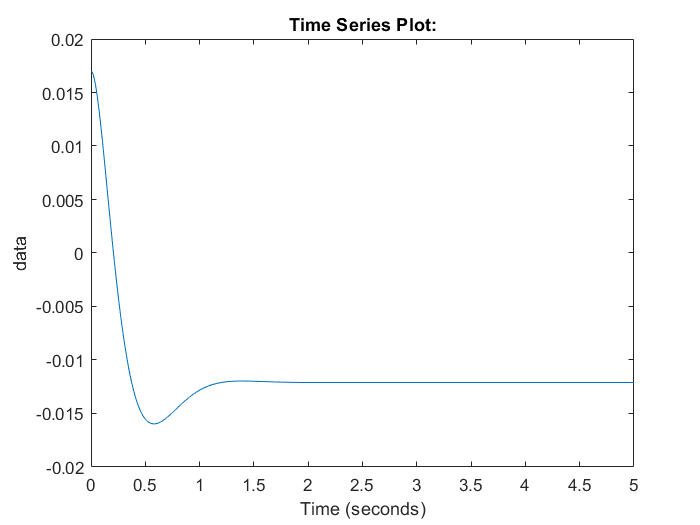

sim("Aufgabe2_2")
figure()
plot(phi)

### c)

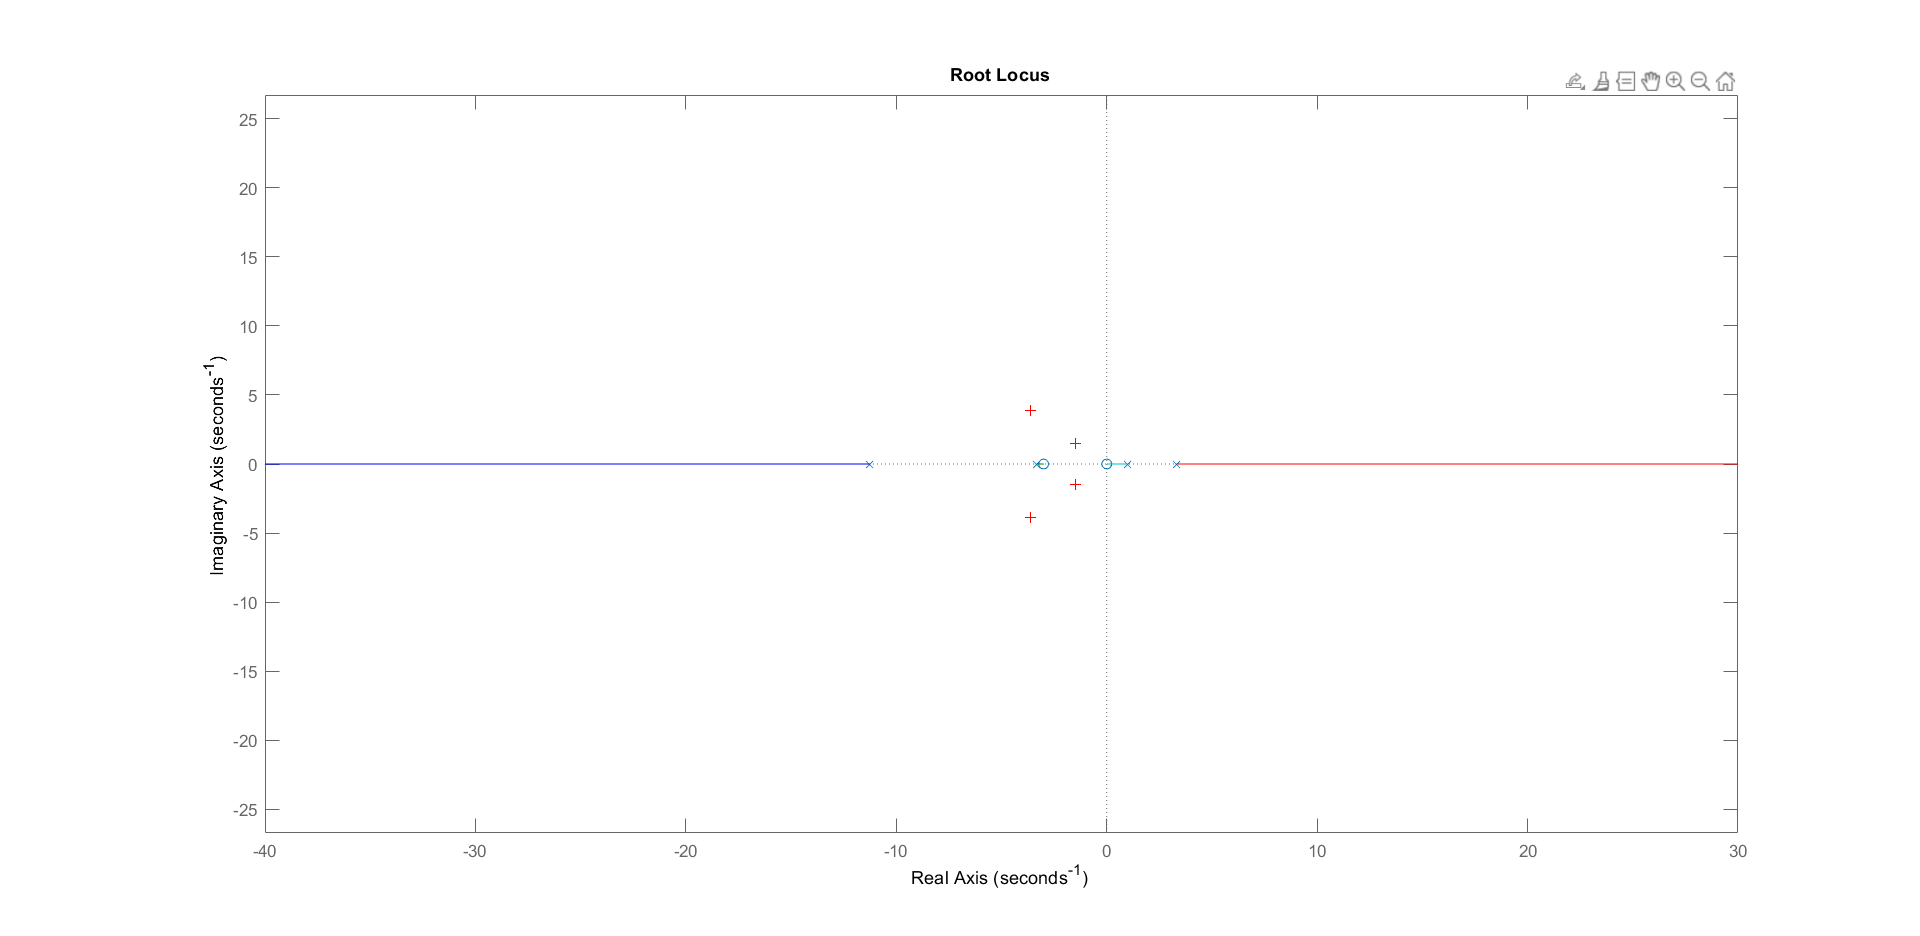

Select a point in the graphics window


selected_point = -3.1466 - 0.1811i

k = 36.9788

poles =   -3.6378 + 3.8539i
  -3.6378 - 3.8539i
  -1.4872 + 1.4934i
  -1.4872 - 1.4934i


Fr2 = (s+3)/(s-1);

Lnum = Fr2*Fe*Fs;
L = minreal(Lnum);

rlocus(-L)

axis equal

[k,poles]=rlocfind(L)



% syms Kr w
% N = 1+Kr*1i*w+3/(1i*w-1)*b0/((1i*w)^2-a0)*u/r*(J/psi)*1i*w/(1+J*R/(psi^2)*1i*w)
% ImN = imag(N)